clc;clear;

% 打开原文件和新文件
fid_in = fopen('.\Data\final\60to30_2.2.log', 'r')

fid_in = 3

fid_out = fopen('.\Data\final\60to30_2.2.txt', 'w')

fid_out = 4

%.\Data\ev_difp\f1.8_45min

% 循环读取每一行
while ~feof(fid_in)
    line = fgetl(fid_in);  % 读取一行
    % 判断并删除开头的 '00>'（含空格）
    if startsWith(line, '00> ')
        line = extractAfter(line, '00> ');
    elseif startsWith(line, '00>')
        line = extractAfter(line, '00>');
    end
    % 写入新文件
    fprintf(fid_out, '%s\n', line);
end

% 关闭文件
fclose(fid_in);
fclose(fid_out);

disp('处理完成！');

处理完成！


% 读取文本文件
filename = '.\Data\data_for_doubleAOA_new\CFO\processed_rtt_files\processed_2m_0_CFO.txt';  % <-- 改成你的文件名
fid = fopen(filename, 'r');
rawData = textscan(fid, '%s', 'Delimiter', '\n');
fclose(fid);



fid = fopen('.\Data\data_for_doubleAOA_new\CFO\processed_rtt_files\processed_2m_0_CFO.txt', 'r'); %这样读入
if fid == -1
    error('File data.txt not found. Please ensure the file exists.');
end
data = fread(fid, '*char')';
fclose(fid);


% Extract all RX Timestamps
rx_pattern = 'RX Timestamp: (\d+)';
rx_matches = regexp(data, rx_pattern, 'tokens');
if isempty(rx_matches)
    error('No RX Timestamps found in the data.');
end
%这里的rx_matches是返回所有匹配rx_pattern的数组、
rx_timestamps = zeros(length(rx_matches), 1);
for i = 1:length(rx_matches)
    rx_timestamps(i) = str2double(rx_matches{i}{1});
end
rx_timestamps

rx_timestamps = 1.0e+12 *

    1.0123
    1.0133
    0.0530
    0.0541
    0.1934
    0.1944
    0.3336
    0.3347
    0.4740
    0.4750


% Extract all Clock Offset Hz values
co_pattern = 'Clock Offset: ([\d\.]+) Hz';
co_matches = regexp(data, co_pattern, 'tokens');
if isempty(co_matches)
    error('No Clock Offset values found in the data.');
end

clock_offsets = zeros(length(co_matches), 1);
for i = 1:length(co_matches)
    clock_offsets(i) = str2double(co_matches{i}{1});
end
mean_CFO = mean(clock_offsets)

mean_CFO = 1.4683e+03

clock_offsets

clock_offsets = 1.0e+03 *

    1.1121
    2.0903
    1.7072
    1.9006
    1.4580
    0.9447
    2.0940
    2.2242
    0.3273
    1.6960



num_rounds  = length(co_matches) / 2;
clock_CFO = zeros(1,num_rounds);
for i = 1:num_rounds
    clock_CFO(i) = ( clock_offsets(2*i-1) + clock_offsets(2*i) )/2;
end

clock_CFO

clock_CFO = 1.0e+03 *

    1.6012    1.8039    1.2013    2.1591    1.0117    1.3185    1.4580    2.0047    1.5231    1.4264    1.7035    1.4952    1.4189    1.2423    1.0377    1.6644    1.3631    1.1325    1.3166    1.5900    1.7592    0.6360    1.0358    1.2237    2.3246    1.5510    1.1809    1.3129    1.4338    1.1121    1.7685    1.9489    1.9731    1.4431    1.8281    1.0135    0.9336    1.5324    0.8424    1.6309    0.7606    0.4947    1.7778    0.5356    0.8778    1.0024    1.7239    1.5286    1.2813    0.8201


% 获取行内容
lines = rawData{1};

% 初始化存储变量
sn_len = [];
% CIR存储结构
Ipatov_CIR = [];
STS0_CIR = [];
STS1_CIR = [];

% 状态标志
current_mode = '';   % 当前是哪种CIR类型（Ipatov / STS0 / STS1）
inside_CIR_block = false;  % 是否正在读取CIR数据

% 遍历每一行，按规则提取
for i = 1:length(lines)
    line = strtrim(lines{i});
    
    if contains(line, 'Sequence Number')
        tokens = regexp(line, 'Sequence Number[:\s]+(\d+)', 'tokens');
        if ~isempty(tokens)
            sn_len = [sn_len, str2double(tokens{1}{1})];
        else
            disp(['Regex failed to match: ', line]);  % 调试用
        end
    end
        
    
 % 检测 CIR 类型标志
    if contains(line, 'Printing Ipatov CIR')
        current_mode = 'Ipatov';
        inside_CIR_block = false;  % 等待进入“-----------”段
    elseif contains(line, 'Printing STS0 CIR')
        current_mode = 'STS0';
        inside_CIR_block = false;  % 等待进入“-----------”段
    elseif contains(line, 'Printing STS1 CIR')
        current_mode = 'STS1';
        inside_CIR_block = false;  % 等待进入“-----------”段 
    end
    
    % 检测 “-----------” 的起始和结束
    if contains(line, '_________________________________')
        inside_CIR_block = ~inside_CIR_block;  % 切换状态
        continue;  % 这行不用处理
    end
    
    % 正在 CIR 数据块内，提取 I, Q
    if inside_CIR_block
        data_tokens = regexp(line, '(-?\d+),(-?\d+)', 'tokens');
        if ~isempty(data_tokens)
            I_val = str2double(data_tokens{1}{1});
            Q_val = str2double(data_tokens{1}{2});
            complex_val = I_val + 1j * Q_val;
            % 根据当前模式放入不同数组
            if strcmp(current_mode, 'Ipatov')
                Ipatov_CIR(end+1, 1) = complex_val;
            elseif strcmp(current_mode, 'STS0')
                STS0_CIR(end+1, 1) = complex_val;
            elseif strcmp(current_mode, 'STS1')
                STS1_CIR(end+1, 1) = complex_val;
            end
        end
    end
end

% 输出到命令行确认

sn_len

sn_len =     84    87   220   223   100   103   236   239   116   119   252   255   132   135    12    15   148   151    28    31   164   167    44    47   180   183    60    63   196   199    76    79   212   215    92    95   228   231   108   111   244   247   124   127     4     7   140   143    20    23


disp(['Sequence Number: ', num2str(sn_len)]);

Sequence Number: 84   87  220  223  100  103  236  239  116  119  252  255  132  135   12   15  148  151   28   31  164  167   44   47  180  183   60   63  196  199   76   79  212  215   92   95  228  231  108  111  244  247  124  127    4    7  140  143   20   23  156  159   36   39  172  175   52   55  188  191   68   71  204  207   84   87  220  223  100  103  236  239  116  119  252  255  132  135   12   15  148  151   28   31  164  167   44   47  180  183   60   63  196  199   76   79  212  215   92   95  228  231  108  111  244  247  124  127    4    7  140  143   20   23  156  159   36   39  172  175   52   55  187  190   67   70  203  206   83   86  219  222   99  102  235  238  115  118  251  254  131  134   11   14  147  150   27   30  163  166   43   46  179  182   59   62  195  198   75   78  211  214   91   94  227  230  107  110  243  246  123  126    3    6  139  142   19   22  155  158   35   38  171  174   50   53  186  189   66   69  202  205   82   85  218  221   98 

%difp中采集到的数据都是5ms左右的，一定要乘以3！

packets_num = floor(length(STS0_CIR)/512);  % 向下取整，确保能reshape成功
STS0_CIR = reshape(STS0_CIR(1:512 * packets_num), 512, packets_num).';
STS1_CIR = reshape(STS1_CIR(1:512 * packets_num), 512, packets_num).';

%有一个奇怪的现象，sequence number每一轮的开头分别是偶数->奇数->偶数，但是rx_timestamps基本是对的
packets_num

packets_num = 220

% 如果 packets_num 是奇数，丢弃最后一行


i = 1

i = 1

while i < packets_num

    % 判断当前数据包索引i是否为偶数



        % 交换STS0_CIR的第i行和第i+1行
     if mod(sn_len(i),2) == 1
     temp = STS0_CIR(i, :);
     STS0_CIR(i, :) = STS0_CIR(i+1, :);
     STS0_CIR(i+1, :) = temp;
     
        % 交换STS1_CIR的第i行和第i+1行
     temp = STS1_CIR(i, :);
     STS1_CIR(i, :) = STS1_CIR(i+1, :);
     STS1_CIR(i+1, :) = temp;

     temp = rx_timestamps(i,:);
     rx_timestamps(i,:) = rx_timestamps(i+1,:);
     rx_timestamps(i+1,:) = temp; %这是进行时间戳的交换
     end

    % 移动到下一组数据包
    i = i + 2;
end

rx_timestamps

rx_timestamps = 1.0e+12 *

    1.0123
    1.0133
    0.0530
    0.0541
    0.1934
    0.1944
    0.3336
    0.3347
    0.4740
    0.4750



if mod(packets_num, 2) ~= 0
    STS0_CIR(end, :) = [];
    STS1_CIR(end, :) = [];
    packets_num = packets_num - 1 ;
end
packets_num

packets_num = 220

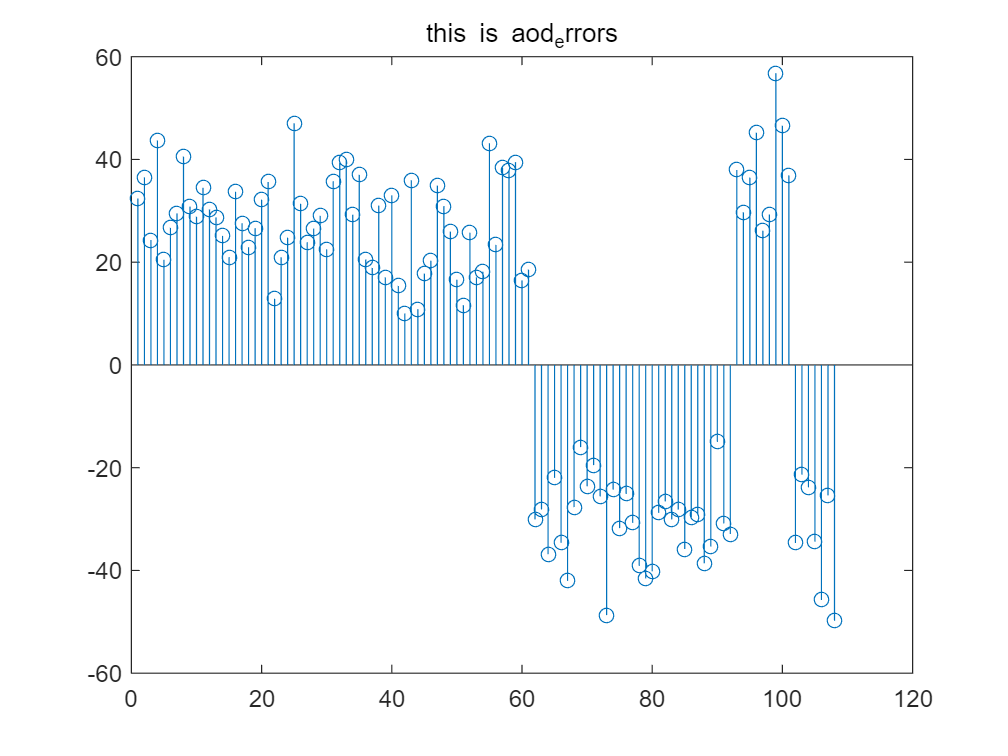


aod_errors = zeros(1, num_rounds);
test_time = zeros(1,num_rounds); %这是用来记录时间戳间隔的
for i = 1:num_rounds
    idx1 = 2*i - 1;
    idx2 = 2*i;
    T1 = rx_timestamps(idx1);
    T2 = rx_timestamps(idx2);
    CFO = clock_CFO(i); % 使用每轮第一个数据包的Clock Offset
    
    delta_t = (T2 - T1) / 1e12 ; % 转换为秒
    %这样就和发包间隔无关了是吗
    test_time(i) = delta_t;
    %aod_errors(i) = 0.000154 * 2 * pi * delta_t * mean_CFO *180 / pi; % 计算AOD_error
    aod_errors(i) =  2 * pi * delta_t * CFO*3;
end
figure;
stem(aod_errors);
title('this is aod_errors');

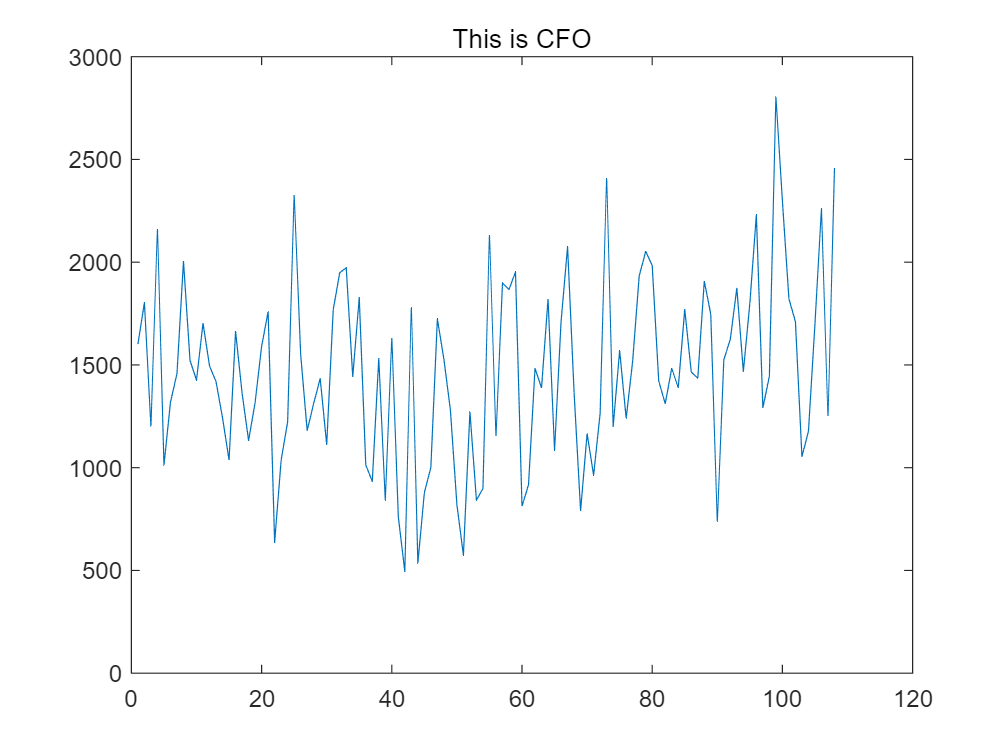

figure;
plot(clock_CFO);
title('This is CFO')

c =physconst("LightSpeed"); % wavelength (assume)
% lambda=c/4992.8e6;
lambda=c/7.9872e9;
antennaSpacing = lambda * 0.5;
% antennaSpacing = 0.0182;

% frequency=4992.8e6;
frequency=7.9872e9;
phase_offset = 0.17;
% -0.67, -0.88, -1.01， -0.72
dis = sqrt((4.4-4.01)*(4.4-4.01) + (2.2-2.01) * (2.2-2.01))

dis = 0.4338

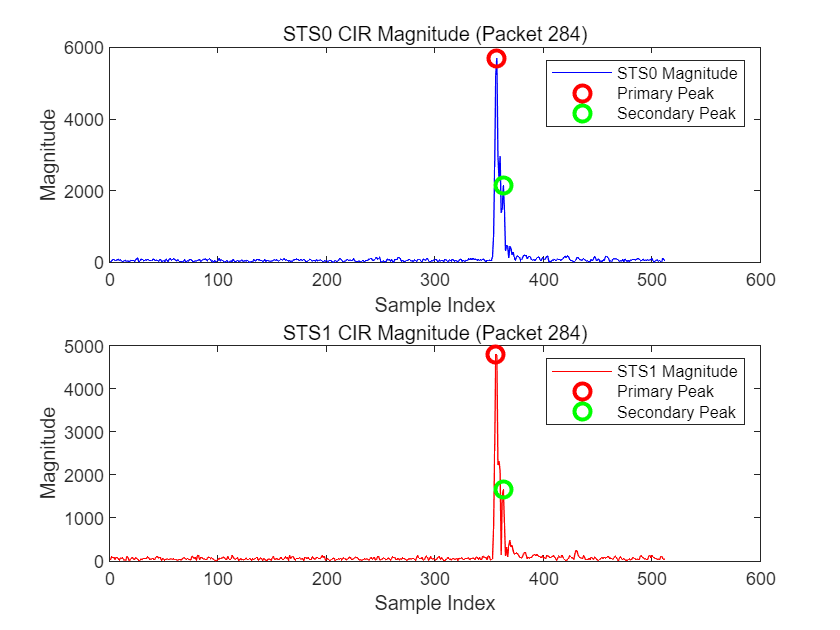

aoa_pdoa_values_main = [];
aoa_degree_values_main = [];

aoa_pdoa_values_secondary = [];
aoa_degree_values_secondary = [];

peaks_index_STS0 = [];
peaks_index_STS1 = [];

for i = 1:packets_num
    % i =2 ;
    % 取出第 i 组 CIR 数据
    STS0_data = STS0_CIR(i,:);  
    STS1_data = STS1_CIR(i,:);
    
    % 幅度
    STS0_magnitude = abs(STS0_data);
    STS1_magnitude = abs(STS1_data);

    threshold = 0.1;  % 阈值
    min_peak_distance = 4;  % 峰值之间最少间隔 4 个采样点
    
    % 找峰值
    [peaks_STS0, locs_STS0] = findpeaks(STS0_magnitude, 'MinPeakHeight', threshold * max(STS0_magnitude), 'MinPeakDistance', min_peak_distance);
    [peaks_STS1, locs_STS1] = findpeaks(STS1_magnitude, 'MinPeakHeight', threshold * max(STS1_magnitude), 'MinPeakDistance', min_peak_distance);


    % 主峰和次强峰索引（需保证至少两个峰被找到）
    if length(locs_STS0) < 2 || length(locs_STS1) < 2
        continue; % 跳过不满足条件的帧
    end

    % 主峰和次强峰索引
    peak_index1_STS0 = locs_STS0(1);
    peak_index2_STS0 = locs_STS0(2);
    
    peak_index1_STS1 = locs_STS1(1);
    peak_index2_STS1 = locs_STS1(2);


    % 保存索引
    peaks_index_STS0 = [peaks_index_STS0; peak_index1_STS0,peak_index2_STS0];
    peaks_index_STS1 = [peaks_index_STS1; peak_index1_STS1,peak_index2_STS1];
    
    %% ---- 主峰相位差计算 ----
    STS0_phase_main = angle(STS0_data(peak_index1_STS1));
    STS1_phase_main = angle(STS1_data(peak_index1_STS1));
    phase_difference_main = STS1_phase_main - STS0_phase_main - phase_offset;
    phase_difference_main = mod(phase_difference_main + pi, 2*pi) - pi;

    theta_radians_main = asin(phase_difference_main * c / (2 * pi * antennaSpacing * frequency));
    theta_degrees_main = rad2deg(theta_radians_main);

    aoa_pdoa_values_main(1,end+1) = phase_difference_main;
    aoa_degree_values_main(1,end+1) = theta_degrees_main;
    
    %% ---- 次强峰相位差计算 ----
    STS0_phase_secondary = angle(STS0_data(peak_index2_STS1));
    STS1_phase_secondary = angle(STS1_data(peak_index2_STS1));
    phase_difference_secondary = STS1_phase_secondary - STS0_phase_secondary - phase_offset;
    phase_difference_secondary = mod(phase_difference_secondary + pi, 2*pi) - pi;

    theta_radians_secondary = asin(phase_difference_secondary * c / (2 * pi * antennaSpacing * frequency));
    theta_degrees_secondary = rad2deg(theta_radians_secondary);

    aoa_pdoa_values_secondary(1,end+1) = phase_difference_secondary;
    aoa_degree_values_secondary(1,end+1) = theta_degrees_secondary;

    % ---- 画图并标记峰值 ----
    figure(100);
    clf; % 清空画布

    subplot(2,1,1);
    plot(STS0_magnitude, 'b');
    hold on;
    plot(peak_index1_STS0, STS0_magnitude(peak_index1_STS0), 'ro', 'MarkerSize', 8, 'LineWidth', 2); % 主峰
    plot(peak_index2_STS0, STS0_magnitude(peak_index2_STS0), 'go', 'MarkerSize', 8, 'LineWidth', 2); % 次强峰
    hold off;
    title(['STS0 CIR Magnitude (Packet ', num2str(i), ')']);
    xlabel('Sample Index');
    ylabel('Magnitude');
    legend('STS0 Magnitude', 'Primary Peak', 'Secondary Peak');

    subplot(2,1,2);
    plot(STS1_magnitude, 'r');
    hold on;
    plot(peak_index1_STS1, STS1_magnitude(peak_index1_STS1), 'ro', 'MarkerSize', 8, 'LineWidth', 2); % 主峰
    plot(peak_index2_STS1, STS1_magnitude(peak_index2_STS1), 'go', 'MarkerSize', 8, 'LineWidth', 2); % 次强峰
    hold off;
    title(['STS1 CIR Magnitude (Packet ', num2str(i), ')']);
    xlabel('Sample Index');
    ylabel('Magnitude');
    legend('STS1 Magnitude', 'Primary Peak', 'Secondary Peak');
    % 
    % % 把当前帧写入视频
    % frame = getframe(gcf);
    % writeVideo(v, frame);
end

time = 1:length(aoa_pdoa_values_main);

函数或变量 'aoa_pdoa_values_main' 无法识别。

figure;
subplot(2,1,1);
plot(time, aoa_pdoa_values_main, '-o', 'LineWidth', 2, 'Color', [0.2 0.6 0.8]);
title('PDOA Value over Time');
xlabel('Time (Pair Index)');
ylabel('PDOA Value');
grid on;

subplot(2,1,2);
plot(time, aoa_degree_values_main, '-s', 'LineWidth', 2, 'Color', [0.8 0.4 0.2]);
title('AOA over Time');
xlabel('Time (Packet Index)');
ylabel('Angle (Degrees)');
grid on;

% 1. 计算平均值
mean_pdoa = mean(aoa_pdoa_values_main);
mean_degree = mean(aoa_degree_values_main);

% 2. 计算标准差
std_pdoa = std(aoa_pdoa_values_main);
std_degree = std(aoa_degree_values_main);
% 显示结果
fprintf('PDOA 平均值: %.2f\n', mean_pdoa);
fprintf('PDOA 标准差: %.2f\n', std_pdoa);

fprintf('\nDegree 平均值: %.2f\n', mean_degree);
fprintf('Degree 标准差: %.2f\n', std_degree);

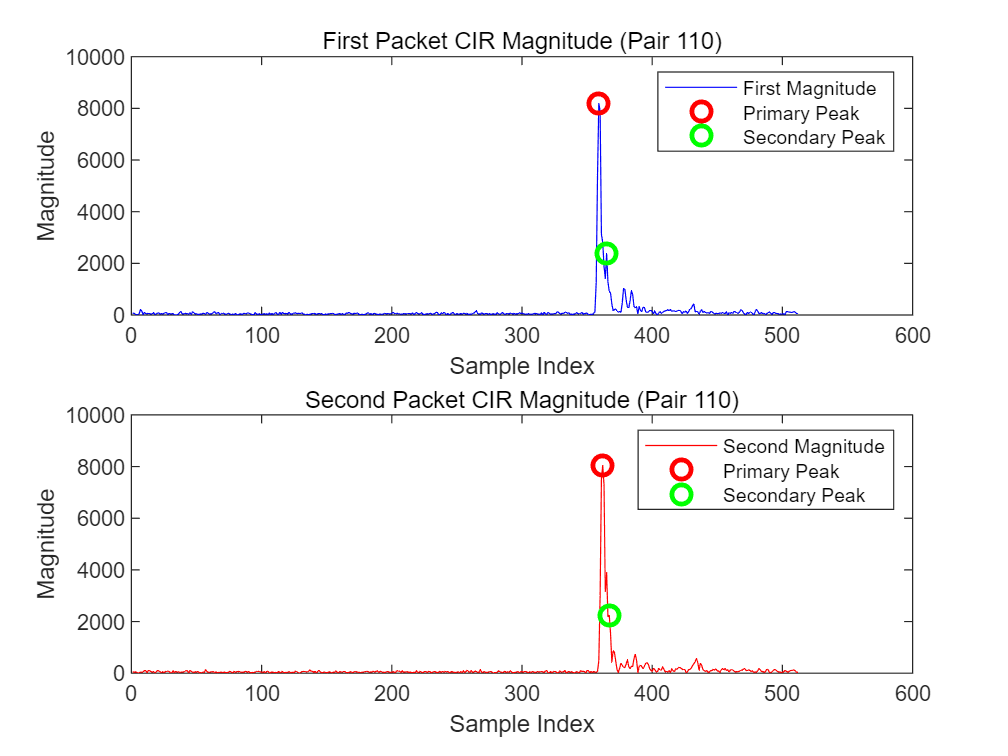

first_packet_cir  = STS0_CIR(1:2:end, :);  % 奇数行
second_packet_cir = STS0_CIR(2:2:end, :);  % 偶数行

aod_pdoa_values_main = [];
aod_degree_values_main = [];


aod_pdoa_values_secondary = [];
aod_degree_values_secondary = [];

peaks_index_first = [];
peaks_index_second = []; %需要在这里把aod_pdoa_values的main和secondary整体减去误差

% video_filename = 'AOD_3.avi';
% v = VideoWriter(video_filename);  % 默认是 Motion JPEG AVI
% v.FrameRate = 5;  % 可根据需要调整帧率
% open(v);


num_pairs = size(first_packet_cir, 1);  % 每组两个packet

for i = 1:num_pairs
    first_data = first_packet_cir(i, :);
    second_data = second_packet_cir(i, :);
    
    % 幅度
    first_magnitude = abs(first_data);
    second_magnitude = abs(second_data);

    threshold = 0.1;
    min_peak_distance = 4;
    
    [peaks_first, locs_first] = findpeaks(first_magnitude, 'MinPeakHeight', threshold * max(first_magnitude), 'MinPeakDistance', min_peak_distance);
    [peaks_second, locs_second] = findpeaks(second_magnitude, 'MinPeakHeight', threshold * max(second_magnitude), 'MinPeakDistance', min_peak_distance);

    % 主峰和次强峰索引（需保证至少两个峰被找到）
    if length(locs_first) < 2 || length(locs_second) < 2
        continue; % 跳过不满足条件的帧
    end

    peak_index1_first = locs_first(1);
    peak_index2_first = locs_first(2);

    peak_index1_second = locs_second(1);
    peak_index2_second = locs_second(2);

   
    peaks_index_first = [peaks_index_first; peak_index1_first, peak_index2_first];
    peaks_index_second = [peaks_index_second; peak_index1_second, peak_index2_second];

    % ---- 主峰相位差计算 ----
    phase_first_main = angle(first_data(peak_index1_first));
    phase_second_main = angle(second_data(peak_index1_second));
    phase_diff_main = phase_second_main - phase_first_main ;
    phase_diff_main = mod(phase_diff_main + pi, 2*pi) - pi;

    theta_rad_main = asin(phase_diff_main * c / (2 * pi * antennaSpacing * frequency));
    theta_deg_main = rad2deg(theta_rad_main);

    aod_pdoa_values_main(end+1) = phase_diff_main;
    aod_degree_values_main(end+1) = theta_deg_main;

    % ---- 次强峰相位差计算 ----
    phase_first_sec = angle(first_data(peak_index2_first));
    phase_second_sec = angle(second_data(peak_index2_second));
    phase_diff_sec = phase_second_sec - phase_first_sec;
    phase_diff_sec = mod(phase_diff_sec + pi, 2*pi) - pi;

    theta_rad_sec = asin(phase_diff_sec * c / (2 * pi * antennaSpacing * frequency));
    theta_deg_sec = rad2deg(theta_rad_sec);

    aod_pdoa_values_secondary(end+1) = phase_diff_sec;
    aod_degree_values_secondary(end+1) = theta_deg_sec;

    % ---- 画图 ----
    figure(100);    
    clf; 
    subplot(2,1,1);
    plot(first_magnitude, 'b');
    hold on;
    plot(peak_index1_first, first_magnitude(peak_index1_first), 'ro', 'MarkerSize', 8, 'LineWidth', 2);
    plot(peak_index2_first, first_magnitude(peak_index2_first), 'go', 'MarkerSize', 8, 'LineWidth', 2);
    title(['First Packet CIR Magnitude (Pair ', num2str(i), ')']);
    xlabel('Sample Index'); ylabel('Magnitude');
    legend('First Magnitude', 'Primary Peak', 'Secondary Peak');

    subplot(2,1,2);
    plot(second_magnitude, 'r');
    hold on;
    plot(peak_index1_second, second_magnitude(peak_index1_second), 'ro', 'MarkerSize', 8, 'LineWidth', 2);
    plot(peak_index2_second, second_magnitude(peak_index2_second), 'go', 'MarkerSize', 8, 'LineWidth', 2);
    title(['Second Packet CIR Magnitude (Pair ', num2str(i), ')']);
    xlabel('Sample Index'); ylabel('Magnitude');
    legend('Second Magnitude', 'Primary Peak', 'Secondary Peak');

    % frame = getframe(gcf);
    % writeVideo(v, frame);
end


fprintf("This is the length of pdoa_main %d",length(aod_pdoa_values_main));

This is the length of pdoa_main 76

% close(v);
% disp(['视频已保存为: ', video_filename]);

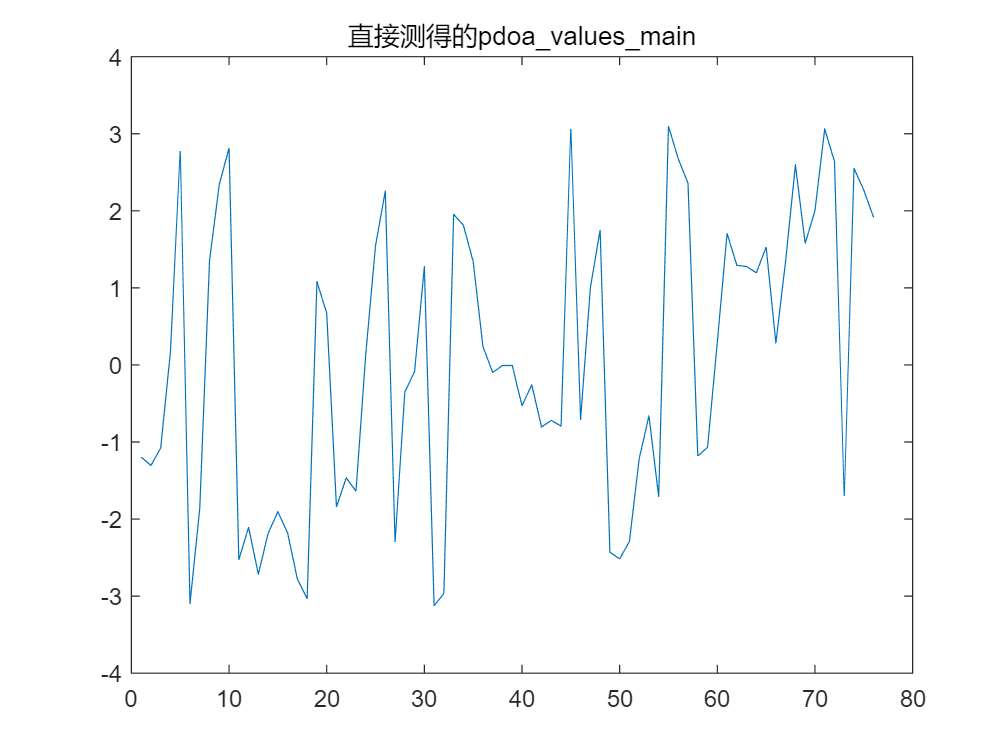


%这一段是对aod_pdoa_values_main进行一个估计CFO的操作的，不能这样
figure;
plot(aod_pdoa_values_main)
title('直接测得的pdoa\_values\_main');

figure;
pd = diff(aod_pdoa_values_main)

pd =    -0.1081    0.2271    1.2506    2.6007   -5.8722    1.2366    3.2139    0.9893    0.4715   -5.3402    0.4195   -0.6085    0.5321    0.2784   -0.2762   -0.5991   -0.2532    4.1153   -0.4093   -2.5131    0.3746   -0.1720    1.7761    1.4110    0.7080   -4.5545    1.9464    0.2652    1.3642   -4.4030    0.1594    4.9201   -0.1426   -0.4692   -1.1040   -0.3362    0.0905   -0.0001   -0.5226    0.2720   -0.5470    0.0852   -0.0744    3.8541   -3.7690    1.7080    0.7518   -4.1806   -0.0877    0.2272


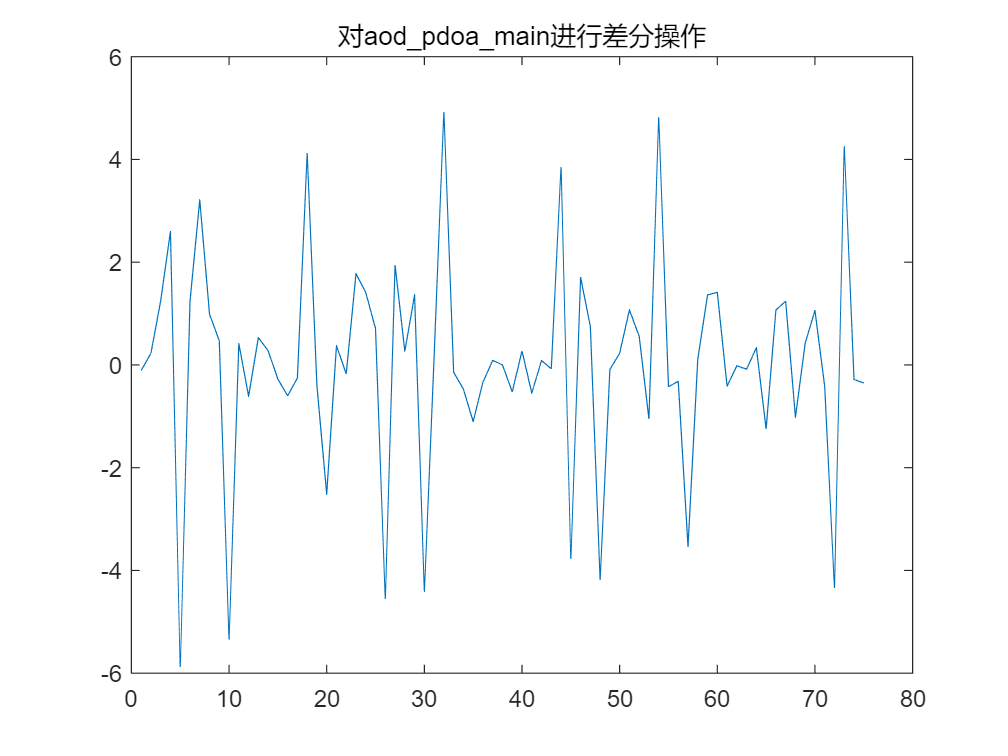

plot(pd)
title('对aod\_pdoa\_main进行差分操作')

for i = 1:num_rounds

    aod_pdoa_values_main_noerror(i) = aod_pdoa_values_main(i) - aod_errors(i);
    aod_pdoa_values_secondary_noerror(i) = aod_pdoa_values_secondary(i) - aod_errors(i);
end

Index exceeds the number of array elements. Index must not exceed 76.

figure;
plot(aod_pdoa_values_main_noerror  )
title('(用总体CFO)矫正误差之后的aod\_pdoa\_main');

figure;
plot(mod(aod_pdoa_values_main_noerror+pi,2*pi)-pi)
title('矫正误差之后再wrap')



N_round = floor(num_rounds/2);
new_aod_pdoa_values_main = zeros(1,N_round);
for i = 1:N_round
    new_aod_pdoa_values_main(i) =( aod_pdoa_values_main(2*i) + aod_pdoa_values_main(2*i-1))/2;
end
half_pdoa_aod = zeros(1,num_rounds)
more_pdoa_aod = zeros(1,num_rounds)
cnt = 0
cnt_more = 0;
for i = 1:num_rounds
    if aod_pdoa_values_main(i) > 0
        cnt = cnt + 1;
        half_pdoa_aod(cnt) = aod_pdoa_values_main(i);
        if cnt>=2
            cnt_more = cnt_more + 1;
            u = mod(half_pdoa_aod(cnt)+pi,2*pi)-pi;
            v = mod(half_pdoa_aod(cnt-1)+pi,2*pi)-pi;
            more_pdoa_aod(cnt_more) = (u+v)/2;
        end
    end
end
figure;
plot(mod(half_pdoa_aod+pi,2*pi)-pi)
title('取矫正之后pdoa大于0的值进行wrap')
figure;
plot(new_aod_pdoa_values_main)

title('great')
figure;
plot(more_pdoa_aod);
title('取half_pdoa进行逐个平均')

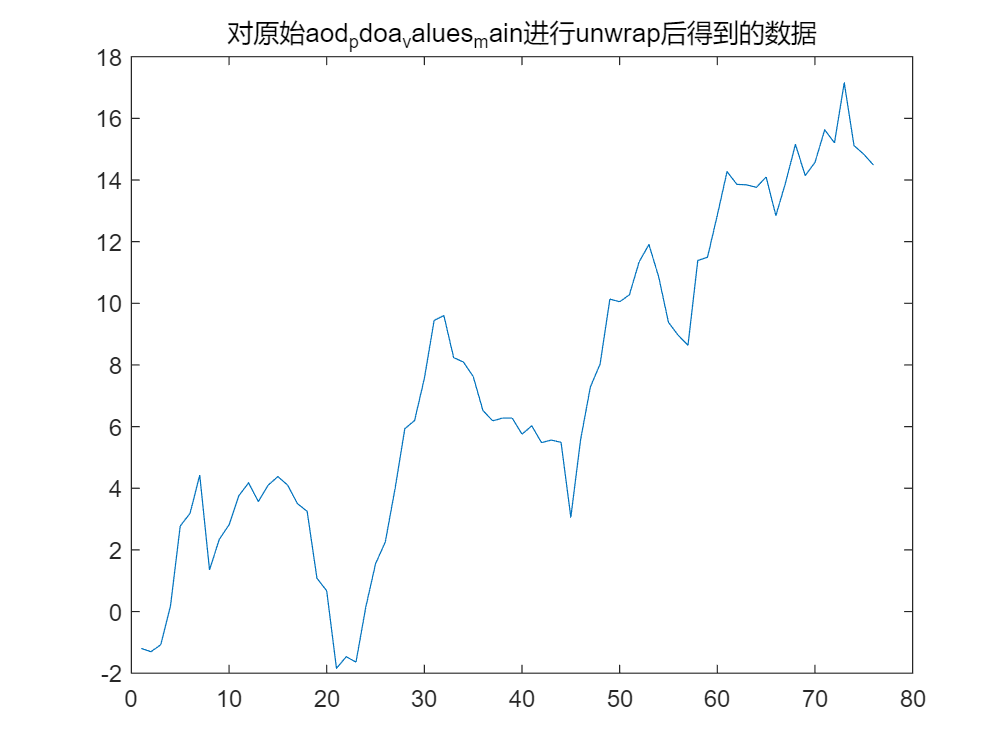

% 假设你已经有以下变量：
% aod_pdoa_values_main, aod_pdoa_values_secondary
% aod_degree_values_main, aod_degree_values_secondary
% 并且它们都是相位（rad）值或角度值序列

% === STEP 1: 相位展开（unwrap） ===
aod_pdoa_values_main_unwrap = unwrap(aod_pdoa_values_main);
aod_pdoa_values_secondary_unwrap = unwrap(aod_pdoa_values_secondary);
figure;
plot(aod_pdoa_values_main_unwrap);
title('对原始aod_pdoa_values_main进行unwrap后得到的数据')

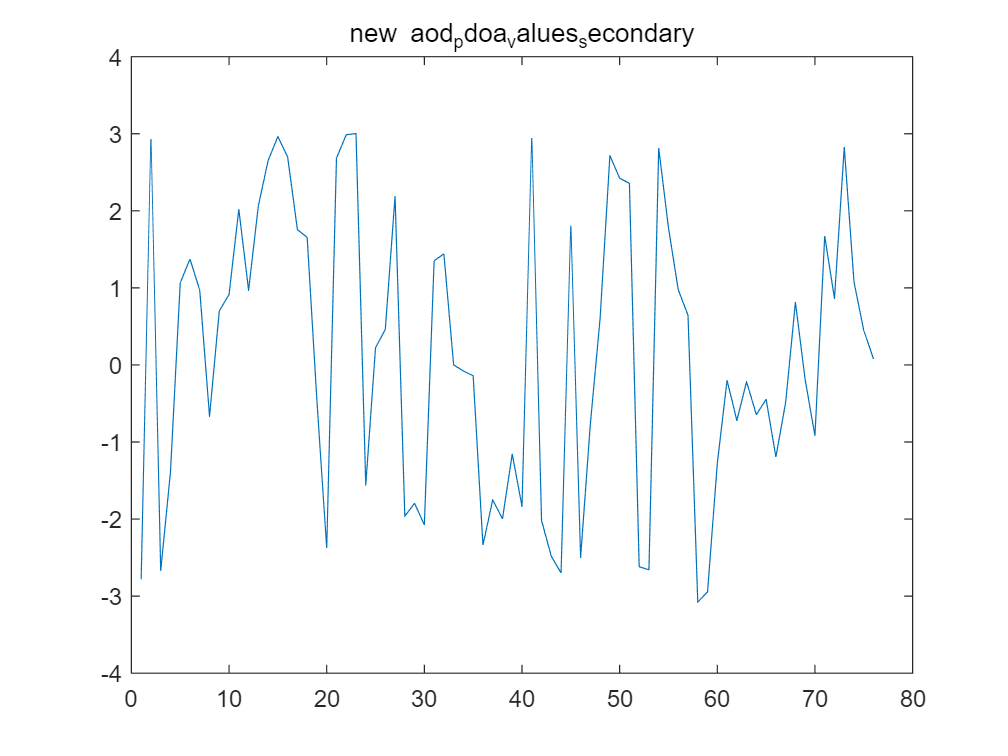


figure;
plot(aod_pdoa_values_secondary);
title('new aod_pdoa_values_secondary')

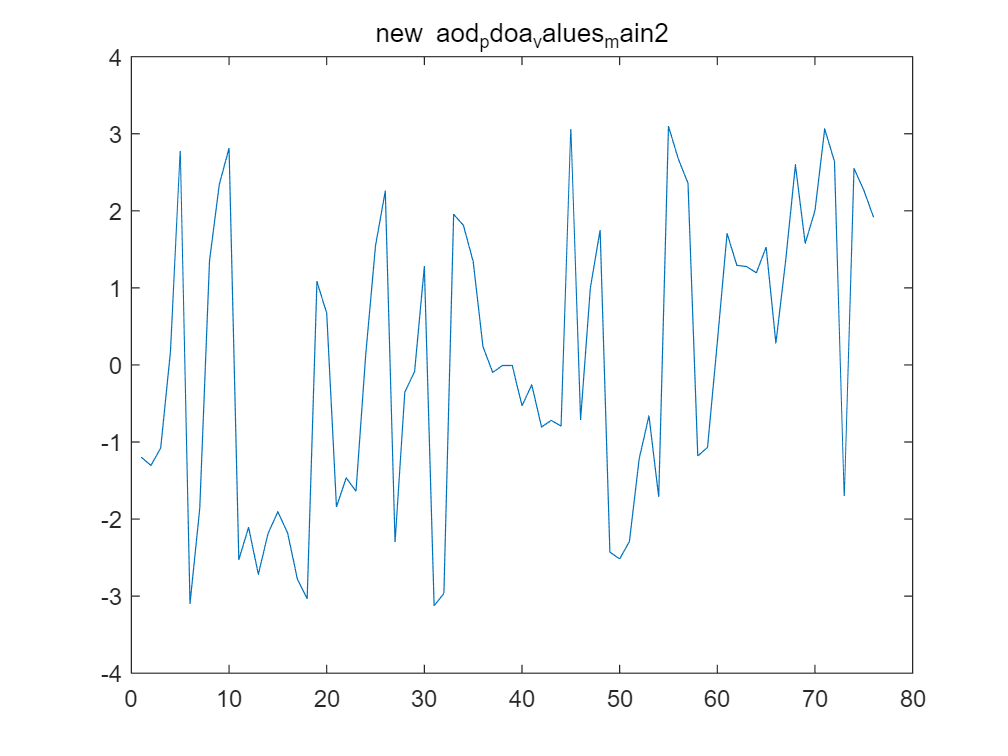

figure;
plot(mod(aod_pdoa_values_main+pi,2*pi)-pi);
title('new aod_pdoa_values_main2');

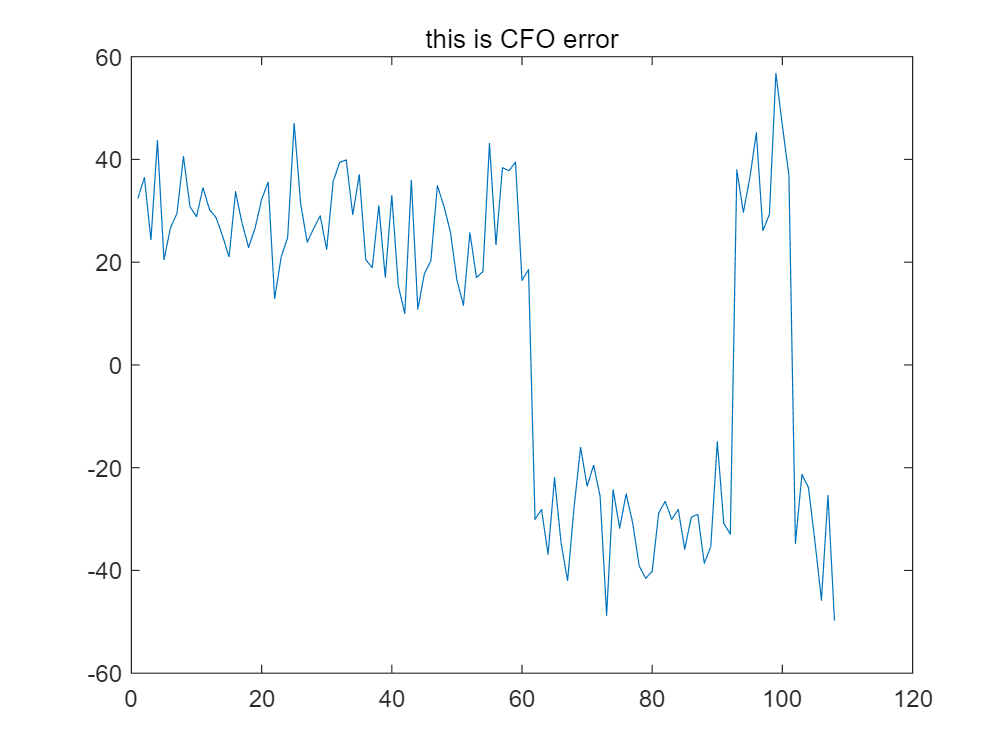


figure;
plot(aod_errors)
title('this is CFO error')


%有办法吗

% 假设你已有一组 wrap 后的 PDOA 相位差
% aod_pdoa_diff_wrapped = ...;

window_size = 10;           % 滑窗大小
residual_thresh = 0.6;      % 剔除残差阈值（rad）

[aod_est_rad, slope_series, cleaned_diff] = ...
    extract_aod_from_pdoa(aod_pdoa_values_main, window_size, residual_thresh);

函数或变量 'extract_aod_from_pdoa' 无法识别。


fprintf('🌟 最终估计的 AoD 相位差（rad）: %.4f\n', aod_est_rad);
fprintf('角度形式（deg）: %.2f°\n', rad2deg(aod_est_rad));


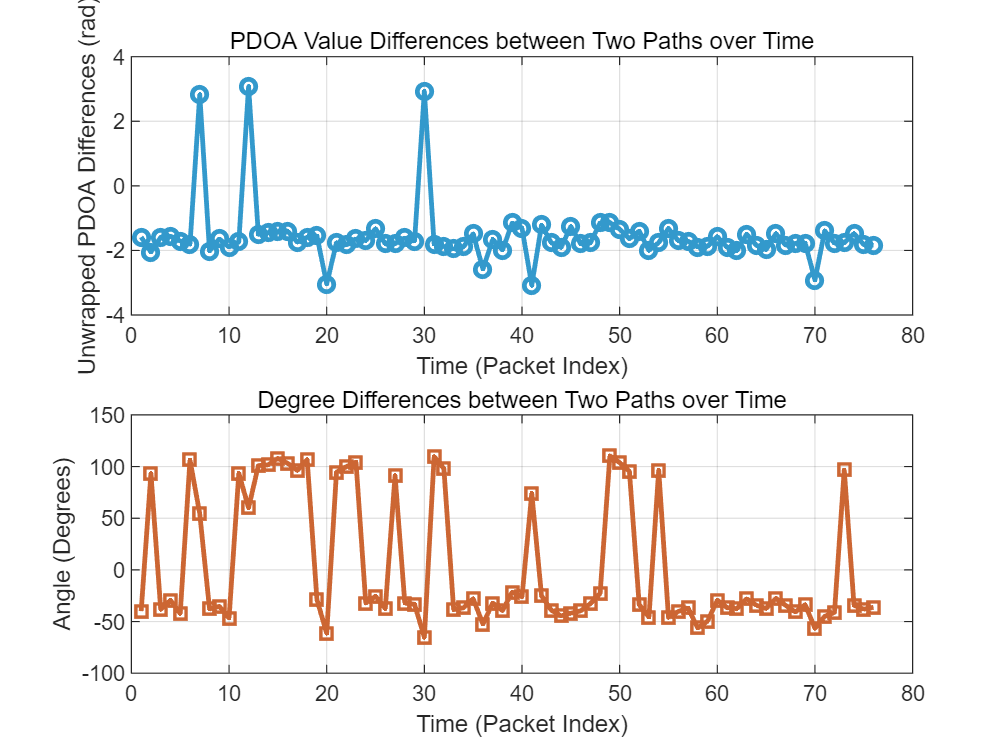


% === STEP 2: 差值计算 ===
time = 1:length(aod_pdoa_values_secondary);

aod_pdoa_diff = aod_pdoa_values_secondary - aod_pdoa_values_main;
aod_pdoa_diff = mod(aod_pdoa_diff + pi, 2*pi) - pi;
aod_degree_diff = aod_degree_values_secondary - aod_degree_values_main;

% === STEP 3: 复数平均 ===
z = exp(1j * aod_pdoa_diff);              % 将相位差转为单位复数向量
z_mean = mean(z);                         % 向量平均
pdoa_phase_mean = angle(z_mean);          % 平均相位差（弧度）
pdoa_phase_std = sqrt(-2*log(abs(z_mean))); % 向量长度 → 相位波动 std 估计

% 同样适用于角度（先转复数再处理）
z_deg = exp(1j * deg2rad(aod_degree_diff));
z_deg_mean = angle(mean(z_deg));          % 平均角度差（弧度）
deg_phase_mean = rad2deg(z_deg_mean);     % 转为角度
deg_phase_std = rad2deg(sqrt(-2*log(abs(mean(z_deg)))));  % 类似 std

% === STEP 4: 绘图 ===
figure;

subplot(2,1,1);
plot(time, aod_pdoa_diff, '-o', 'LineWidth', 2, 'Color', [0.2 0.6 0.8]);
title('PDOA Value Differences between Two Paths over Time');
xlabel('Time (Packet Index)');
ylabel('Unwrapped PDOA Differences (rad)');
grid on;

subplot(2,1,2);
plot(time, aod_degree_diff, '-s', 'LineWidth', 2, 'Color', [0.8 0.4 0.2]);
title('Degree Differences between Two Paths over Time');
xlabel('Time (Packet Index)');
ylabel('Angle (Degrees)');
grid on;


% === STEP 5: 显示复数平均结果 ===
fprintf('== 使用复数平均法 ==\n');

== 使用复数平均法 ==


fprintf('PDOA 平均相位差 (rad): %.4f\n', pdoa_phase_mean);

PDOA 平均相位差 (rad): -1.7639


fprintf('PDOA 相位差波动（类似标准差）(rad): %.4f\n', pdoa_phase_std);

PDOA 相位差波动（类似标准差）(rad): 0.4568


fprintf('\nAngle 平均角度差 (deg): %.2f\n', deg_phase_mean);


Angle 平均角度差 (deg): -14.16


fprintf('Angle 相位波动（类似标准差）(deg): %.2f\n', deg_phase_std);

Angle 相位波动（类似标准差）(deg): 64.54


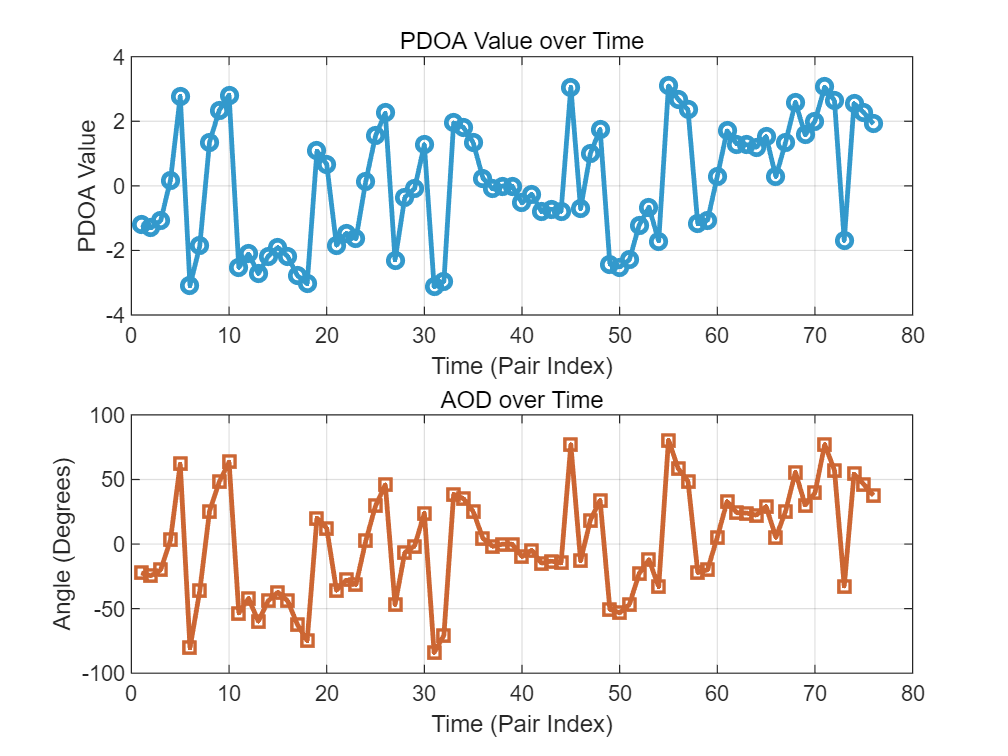

time = 1:length(aod_pdoa_values_main);
figure;
subplot(2,1,1);
plot(time, aod_pdoa_values_main, '-o', 'LineWidth', 2, 'Color', [0.2 0.6 0.8]);
title('PDOA Value over Time');
xlabel('Time (Pair Index)');
ylabel('PDOA Value');
grid on;

subplot(2,1,2);
plot(time, aod_degree_values_main, '-s', 'LineWidth', 2, 'Color', [0.8 0.4 0.2]);
title('AOD over Time');
xlabel('Time (Pair Index)');
ylabel('Angle (Degrees)');
grid on;


% 1. 计算平均值
mean_pdoa = mean(aod_pdoa_values_main);
mean_degree = mean(aod_degree_values_main);

% 2. 计算标准差
std_pdoa = std(aod_pdoa_values_main);
std_degree = std(aod_degree_values_main);
% 显示结果
fprintf('PDOA 平均值: %.2f\n', mean_pdoa);

PDOA 平均值: 0.04


fprintf('PDOA 标准差: %.2f\n', std_pdoa);

PDOA 标准差: 1.87



fprintf('\nDegree 平均值: %.2f\n', mean_degree);


Degree 平均值: 0.68


fprintf('Degree 标准差: %.2f\n', std_degree);

Degree 标准差: 40.90


time = 1:length(aod_pdoa_values_secondary);
aod_pdoa_diff = aod_pdoa_values_secondary - aod_pdoa_values_main;
aod_pdoa_diff = mod(aod_pdoa_diff + pi, 2*pi) - pi;
% aod_degree_diff= asin(aod_pdoa_diff * c / (2 * pi * antennaSpacing * frequency));
% aod_degree_diff = rad2deg(aod_pdoa_diff);
aod_degree_diff = aod_degree_values_secondary - aod_degree_values_main;
aod_sin_diff = aod_pdoa_diff*c / (2*pi*frequency*antennaSpacing)

aod_sin_diff =    -0.5046   -0.6525   -0.5079   -0.4976   -0.5441   -0.5761    0.9003   -0.6428   -0.5227   -0.6042   -0.5531    0.9795   -0.4782   -0.4605   -0.4502   -0.4465   -0.5559   -0.5076   -0.4935   -0.9691   -0.5601   -0.5824   -0.5228   -0.5398   -0.4218   -0.5719   -0.5710   -0.5126   -0.5442    0.9325   -0.5747   -0.5977   -0.6219   -0.6020   -0.4723   -0.8202   -0.5264   -0.6332   -0.3657   -0.4157   -0.9814   -0.3859   -0.5612   -0.6067   -0.4001   -0.5702   -0.5615   -0.3638   -0.3622   -0.4271


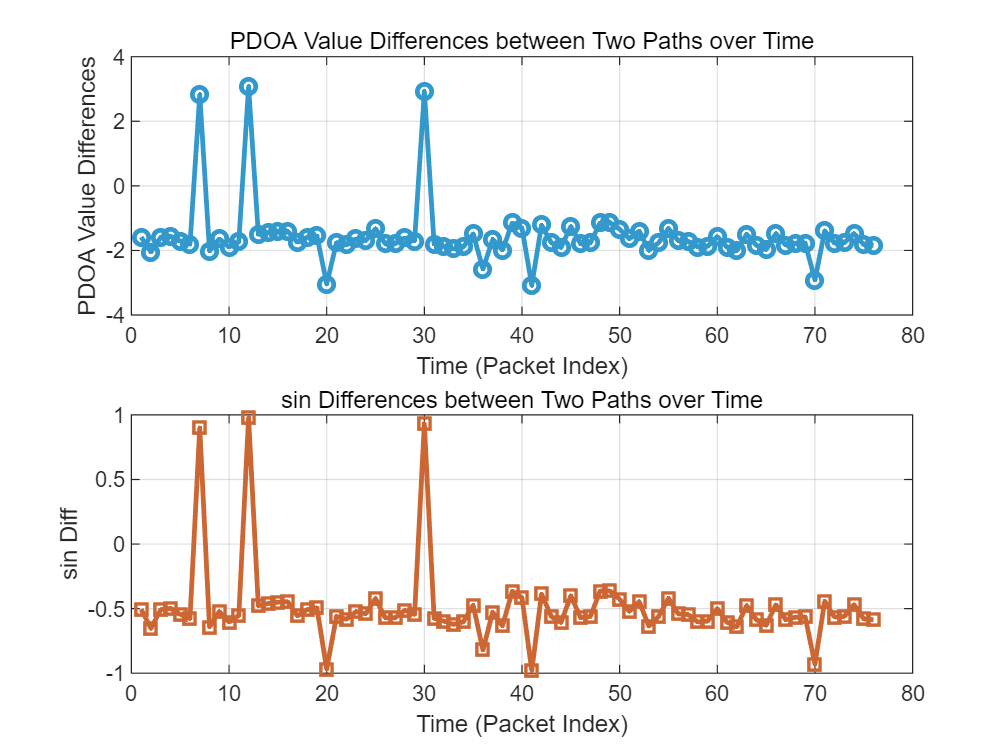

figure;
subplot(2,1,1);
plot(time, aod_pdoa_diff, '-o', 'LineWidth', 2, 'Color', [0.2 0.6 0.8]);
title('PDOA Value Differences between Two Paths over Time');
xlabel('Time (Packet Index)');
ylabel('PDOA Value Differences');
grid on;

subplot(2,1,2);
plot(time, aod_sin_diff, '-s', 'LineWidth', 2, 'Color', [0.8 0.4 0.2]);
title('sin Differences between Two Paths over Time');
xlabel('Time (Packet Index)');
ylabel('sin Diff');
grid on;


% 1. 计算平均值
mean_pdoa = mean(aod_pdoa_diff);
mean_sin = mean(aod_sin_diff);

% 2. 计算标准差
std_pdoa = std(aod_pdoa_diff);
std_sin = std(aod_sin_diff);
% 显示结果
fprintf('PDOA 平均值: %.2f\n', mean_pdoa);

PDOA 平均值: -1.55


fprintf('PDOA 标准差: %.2f\n', std_pdoa);

PDOA 标准差: 0.98



fprintf('\nsin 平均值: %.2f\n', mean_sin);


sin 平均值: -0.49


fprintf('sin 标准差: %.2f\n', std_sin);

sin 标准差: 0.31


%PDOA1.97,大约稳定在38.8°左右

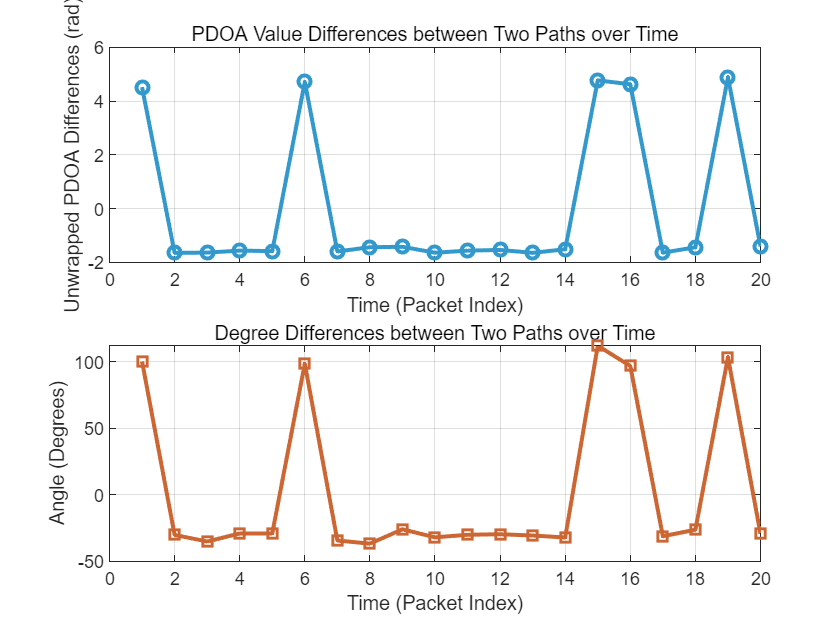

% === STEP 2: 差值计算 ===
time = 1:length(aod_pdoa_values_secondary);
aod_pdoa_diff = aod_pdoa_values_secondary - aod_pdoa_values_main;
aod_degree_diff = aod_degree_values_secondary - aod_degree_values_main;

% === STEP 3: 复数平均 ===
z = exp(1j * aod_pdoa_diff);              % 将相位差转为单位复数向量
z_mean = mean(z);                         % 向量平均
pdoa_phase_mean = angle(z_mean);          % 平均相位差（弧度）
pdoa_phase_std = sqrt(-2*log(abs(z_mean))); % 向量长度 → 相位波动 std 估计

% 同样适用于角度（先转复数再处理）
z_deg = exp(1j * deg2rad(aod_degree_diff));
z_deg_mean = angle(mean(z_deg));          % 平均角度差（弧度）
deg_phase_mean = rad2deg(z_deg_mean);     % 转为角度
deg_phase_std = rad2deg(sqrt(-2*log(abs(mean(z_deg)))));  % 类似 std

% === STEP 4: 绘图 ===
figure;

subplot(2,1,1);
plot(time, aod_pdoa_diff, '-o', 'LineWidth', 2, 'Color', [0.2 0.6 0.8]);
title('PDOA Value Differences between Two Paths over Time');
xlabel('Time (Packet Index)');
ylabel('Unwrapped PDOA Differences (rad)');
grid on;

subplot(2,1,2);
plot(time, aod_degree_diff, '-s', 'LineWidth', 2, 'Color', [0.8 0.4 0.2]);
title('Degree Differences between Two Paths over Time');
xlabel('Time (Packet Index)');
ylabel('Angle (Degrees)');
grid on;


% === STEP 5: 显示复数平均结果 ===
fprintf('== 使用复数平均法 ==\n');

== 使用复数平均法 ==


fprintf('PDOA 平均相位差 (rad): %.4f\n', pdoa_phase_mean);

PDOA 平均相位差 (rad): -1.5553


fprintf('PDOA 相位差波动（类似标准差）(rad): %.4f\n', pdoa_phase_std);

PDOA 相位差波动（类似标准差）(rad): 0.0980


fprintf('\nAngle 平均角度差 (deg): %.2f\n', deg_phase_mean);


Angle 平均角度差 (deg): -13.57


fprintf('Angle 相位波动（类似标准差）(deg): %.2f\n', deg_phase_std);

Angle 相位波动（类似标准差）(deg): 57.33


time = 1:length(aod_pdoa_values_secondary);
aod_pdoa_diff = aod_pdoa_values_secondary - aod_pdoa_values_main;
aod_pdoa_diff = abs(mod(aod_pdoa_diff + pi, 2*pi) - pi);
aod_sin_diff = aod_pdoa_diff*c / (2*pi*frequency*antennaSpacing)

aod_sin_diff =     0.5622    0.5228    0.5195    0.4960    0.5019    0.4996    0.5063    0.4558    0.4509    0.5208    0.4961    0.4881    0.5224    0.4798    0.4819    0.5280    0.5203    0.4569    0.4449    0.4469




% 弧度转换为角度
aod_degree_diff = rad2deg(aod_pdoa_diff);  % 注意这里不再使用asin公式
% aod_degree_diff = abs(aod_degree_values_secondary - aod_degree_values_main);


% ----------- 滤除异常值（使用Z-score法） -------------
% 对 PDOA 进行异常值剔除
z_pdoa = abs((aod_pdoa_diff - mean(aod_pdoa_diff)) / std(aod_pdoa_diff));
valid_idx_pdoa = z_pdoa < 1;  % 3σ内为正常值
%valid_idx_pdoa = 2 > aod_pdoa_diff
filtered_pdoa = aod_pdoa_diff(valid_idx_pdoa);
filtered_sin = aod_sin_diff(valid_idx_pdoa)

filtered_sin =     0.5228    0.5195    0.4960    0.5019    0.4996    0.5063    0.5208    0.4961    0.4881    0.5224    0.4798    0.4819    0.5203



% 对 Degree 进行异常值剔除
z_degree = abs((aod_degree_diff - mean(aod_degree_diff)) / std(aod_degree_diff));
valid_idx_degree = z_degree < 3;
filtered_degree = aod_degree_diff(valid_idx_degree);

% 滤除后的时间轴（可选）
filtered_time_pdoa = time(valid_idx_pdoa);
filtered_time_degree = time(valid_idx_degree);
filtered_time_sin = time(valid_idx_pdoa)

filtered_time_sin =      2     3     4     5     6     7    10    11    12    13    14    15    17


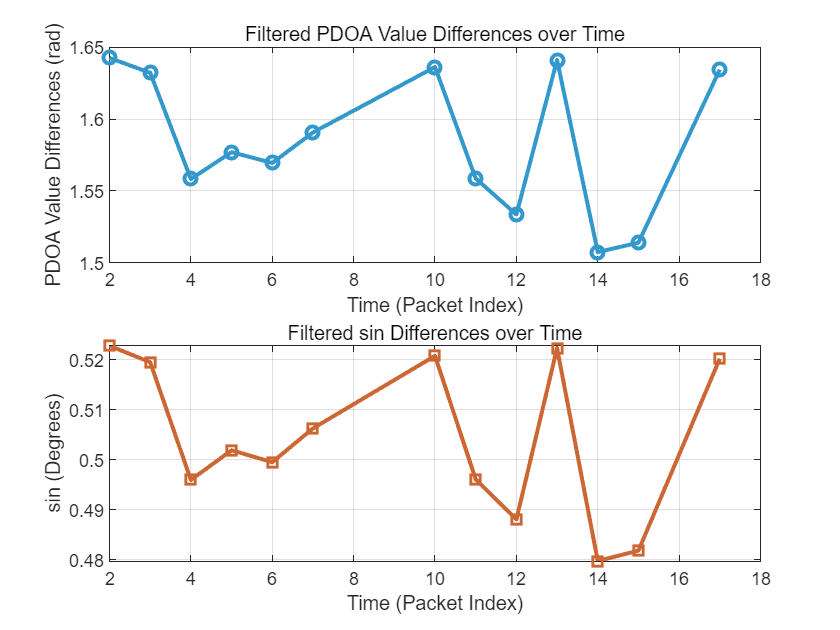

%这里直接用filterd_pdoa去估计filtered_time_sin的值了

% ---------------- 绘图 ----------------
figure;
subplot(2,1,1);
plot(filtered_time_pdoa, filtered_pdoa, '-o', 'LineWidth', 2, 'Color', [0.2 0.6 0.8]);
title('Filtered PDOA Value Differences over Time');
xlabel('Time (Packet Index)');
ylabel('PDOA Value Differences (rad)');
grid on;

subplot(2,1,2);
plot(filtered_time_pdoa, filtered_sin, '-s', 'LineWidth', 2, 'Color', [0.8 0.4 0.2]);
title('Filtered sin Differences over Time');
xlabel('Time (Packet Index)');
ylabel('sin (Degrees)');
grid on;


% ---------------- 输出统计量 ----------------
fprintf('--- After Filtering ---\n');

--- After Filtering ---


fprintf('PDOA 平均值: %.4f rad\n', mean(filtered_pdoa));

PDOA 平均值: 1.5842 rad


fprintf('PDOA 标准差: %.4f rad\n', std(filtered_pdoa));

PDOA 标准差: 0.0494 rad



fprintf('\nsin 平均值: %.2f°\n', mean(filtered_sin));


sin 平均值: 0.50°


fprintf('sin 标准差: %.2f°\n', std(filtered_sin));

sin 标准差: 0.02°



%测算一下
%天线阵列校准与时钟质量可能出现问题，is it true???????????
%

function arr = swapElements(arr, i, j)
    temp = arr(i);
    arr(i) = arr(j);
    arr(j) = temp;
end